addpath('functions/');

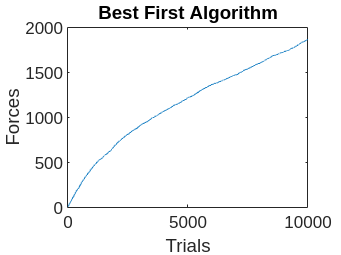

% Creating n Corticalspinal cells
n = 1000;

% Initalize the base CS cells using Uniform Random distribution
x_0 = -1 + (1+1)*rand(1, n);

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

% CS extensor and flexor connection weights
c_fi = ones(1, n); 
c_ei = [zeros(1, n*0.7), -ones(1, n*0.3)]; 

agonist = randperm(n * 0.99);
antagonist = randsample(agonist,length(agonist) / 3);

% Translating MN pool to force
delta = 1;

final_forces = [];
sei_activations = [];
sfi_activations = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;

    s_fi = 0;
    s_ei = 0;
    
    % Facilitate
    for i = 1:length(agonist)
        ind = agonist(i);
        temp = g_i(x_i(ind), c_fi(ind));
        s_fi = s_fi + temp;
    end

    % Inhibit
    for i = 1:length(antagonist)
        ind = antagonist(i);
        temp = g_i(x_i(ind), c_ei(ind));
        s_ei = s_ei + temp;
    end

    f_f = delta * s_fi;
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end

    sei_activations = [sei_activations, s_ei];
    sfi_activations = [sfi_activations, s_fi];
    final_forces = [final_forces, f_final_net];
end

plot(final_forces)
title("Best First Algorithm")
ylabel('Forces')
xlabel('Trials')

saveas(gcf,'images/BestFirstAlgo.png')

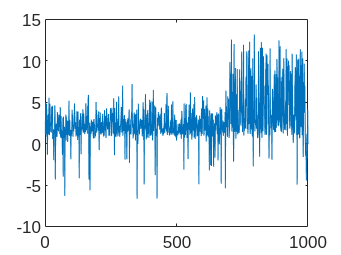

plot(x_0)

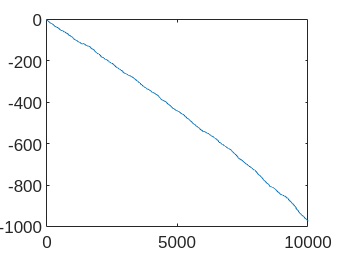

plot(sei_activations)

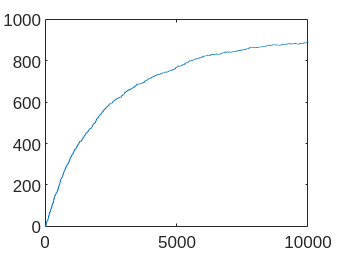

plot(sfi_activations)